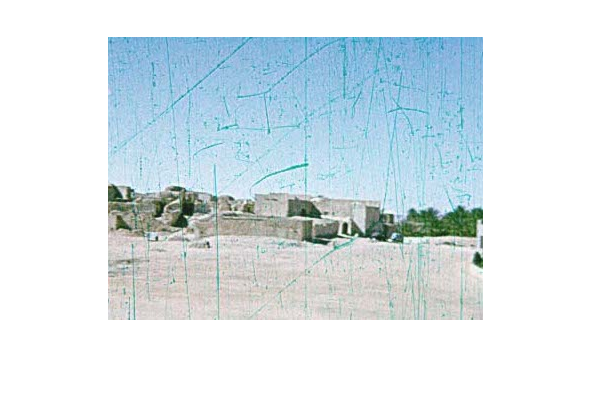

img = imread('Important_files/film1_small.jpg');

imshow(img, []);

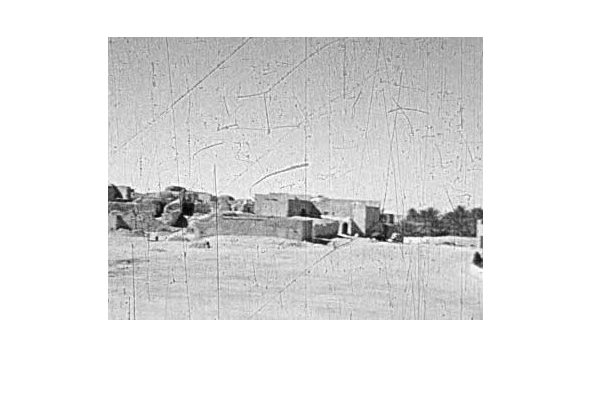


img_oc = img(:,:,2);

imshow(img_oc,[]);

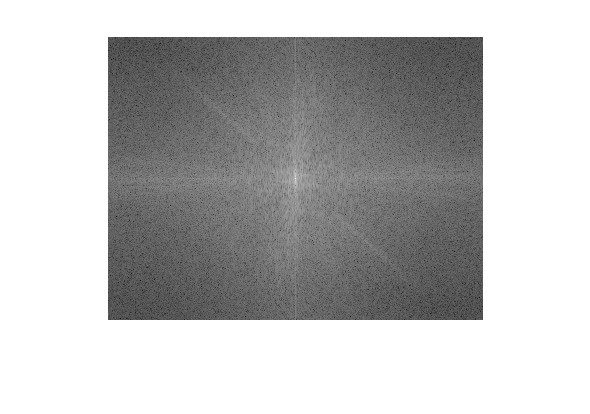

dft = fftshift(fft2(img_oc));

imshow(log(abs(dft)), []);

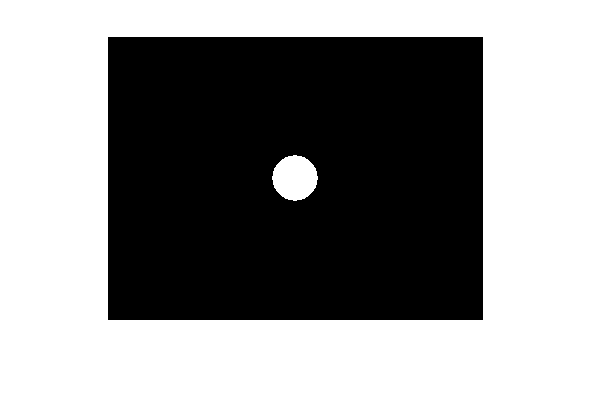


D0 = 1/8 * sqrt(2*128^2);
[rows,cols] = size(dft);
maxu = cols/2;
maxv = rows/2;
u = linspace(1, 2*maxu, 2*maxu) - maxu;
v = linspace(1, 2*maxv, 2*maxv) - maxv;
[uu,vv] = meshgrid(u,v);
filter = (sqrt(uu.^2 + vv.^2) <= D0);
%filter = (exp(-(uu.^2 + vv.^2)./(2*D0^2)));
imshow(filter, [])

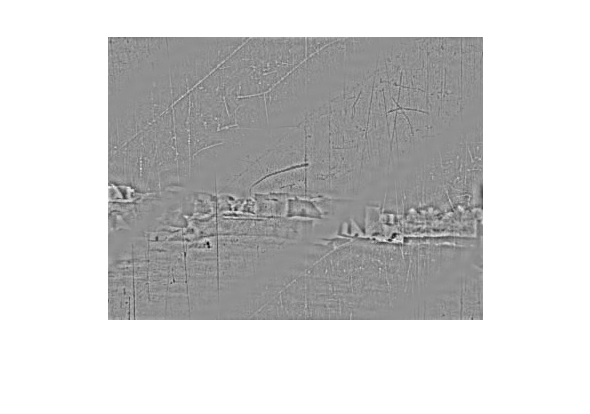


filter_high_pass = 1 -  filter;

filtered_high_pass = filter_high_pass.*dft;

filtered_high_pass_spatial = real(ifft2(fftshift(filtered_high_pass)));

imshow(filtered_high_pass_spatial, []);